Experiments for circular structure


SNRS = [0,40,80,Inf];
iters = 100;

%% initialized exp_data %%
init_SNR_iters = [];
rnd_SNR_iters = [];
exp_data.iterations = [];
exp_data.type = [];
exp_data.SNR = ones(1,iters*2)*SNRS(1);
exp_data.SNR = [exp_data.SNR, ones(1,iters*2)*SNRS(2)];
exp_data.SNR = [exp_data.SNR, ones(1,iters*2)*SNRS(3)];
exp_data.SNR = [exp_data.SNR, ones(1,iters*2)*SNRS(4)];
options = struct;
options.TolFun = eps^2;
options.TolX = eps;
options.LargeScale = false;
%% -----------------   %%
for SNR=1:size(SNRS,2)
    init_iterations = [];
    rnd_iterations = [];
    for iter=1:iters
        dim = [20,20,20];
        T = zeros(dim);
        for i = 1:dim(1)
            T(i,:,:) = circulant(randi([-100,100],size(T,2),1));
        end

        x = randi([-100,100],size(T,2),1);
    
        b = tmprod(T,{x.',x.'},[2,3]);
        b_noisy = noisy(b,SNRS(SNR));
        T_noisy = noisy(T,SNRS(SNR));
        T_noisy_dup  = T_noisy;


        F = 1/sqrt(dim(2))*dftmtx(dim(2));
        F_list = {F,conj(F)};
        omega = tmprod(T_noisy_dup,F_list,[2,3]);

        T_noisy_dup = zeros(size(omega));

        for k = 1:size(T,1)
            T_noisy_dup(k,:,:) = diag(diag(squeeze(omega(k,:,:))));
        end

        y = solve_part_diag(T_noisy_dup,b);
        xest = F\y;   
     
        U0 = {xest,xest};
        [U,output] = lscpd_nls(T_noisy,b,U0,options);
        init_iterations = [init_iterations,output.iterations];

        %%collecting data
        exp_data.iterations = [exp_data.iterations,output.iterations];
        exp_data.type = [exp_data.type,1];
        %%--------------%%

        U0 = cpd_rnd(dim(2:3),1);
        [U2,output2] = lscpd_nls(T_noisy,b,U0,options);

        %%collecting data
        rnd_iterations= [rnd_iterations,output2.iterations];
        exp_data.iterations = [exp_data.iterations,output2.iterations];
        exp_data.type = [exp_data.type,0];
        %%--------------%%
    end
    init_SNR_iters = [init_SNR_iters;init_iterations];
    rnd_SNR_iters = [rnd_SNR_iters;rnd_iterations];
end

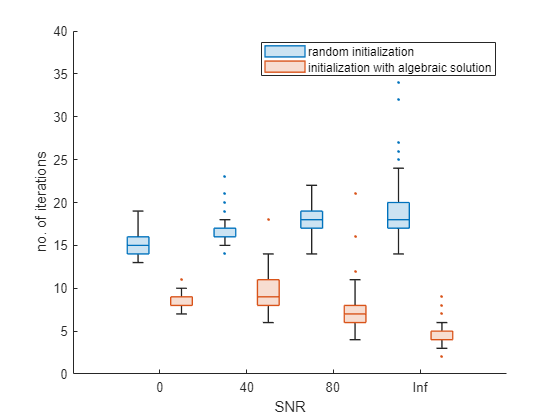

boxchart(categorical(exp_data.SNR),exp_data.iterations,'GroupByColor',exp_data.type,"MarkerStyle",".")
ylabel('no. of iterations')
xlabel('SNR')
%title('iterations required for optimization function(noise on the coeffiecient tensor,\{2,3\} circ)')
legend('random initialization','initialization with algebraic solution')
legend
ylim([0,40])

SNRS = [0,40,80,Inf];
iters = 100;

%% initialized exp_data %%
init_SNR_iters = [];
rnd_SNR_iters = [];
exp_data.iterations = [];
exp_data.type = [];
exp_data.SNR = ones(1,iters*2)*SNRS(1);
exp_data.SNR = [exp_data.SNR, ones(1,iters*2)*SNRS(2)];
exp_data.SNR = [exp_data.SNR, ones(1,iters*2)*SNRS(3)];
exp_data.SNR = [exp_data.SNR, ones(1,iters*2)*SNRS(4)];
options = struct;
options.TolFun = eps^2;
options.TolX = eps;
options.LargeScale = false;

%% -----------------   %%
for SNR=1:size(SNRS,2)
    init_iterations = [];
    rnd_iterations = [];
    for iter=1:iters
        dim = [20,20,20];
        T = zeros(dim);
        for i = 1:dim(1)
            T(i,:,:) = circulant(randi([-100,100],size(T,2),1));
        end

        x = randi([-100,100],size(T,2),1);
    
        b = tmprod(T,{x.',x.'},[2,3]);
        b_noisy = noisy(b,SNRS(SNR));
        T_noisy = noisy(T,SNRS(SNR));
        T_noisy_dup  = T_noisy;


        F = 1/sqrt(dim(2))*dftmtx(dim(2));
        F_list = {F,conj(F)};
        omega = tmprod(T_noisy_dup,F_list,[2,3]);

        T_noisy_dup = zeros(size(omega));

        for k = 1:size(T,1)
            T_noisy_dup(k,:,:) = diag(diag(squeeze(omega(k,:,:))));
        end

        y = solve_part_diag(T_noisy_dup,b_noisy);
        xest = F\y;   
     
        U0 = {xest,xest};
        [U,output] = lscpd_nls(T_noisy,b_noisy,U0,options);
        init_iterations = [init_iterations,output.iterations];

        %%collecting data
        exp_data.iterations = [exp_data.iterations,output.iterations];
        exp_data.type = [exp_data.type,1];
        %%--------------%%

        U0 = cpd_rnd(dim(2:3),1);
        [U2,output2] = lscpd_nls(T_noisy,b_noisy,U0,options);

        %%collecting data
        rnd_iterations= [rnd_iterations,output2.iterations];
        exp_data.iterations = [exp_data.iterations,output2.iterations];
        exp_data.type = [exp_data.type,0];
        %%--------------%%
    end
    init_SNR_iters = [init_SNR_iters;init_iterations];
    rnd_SNR_iters = [rnd_SNR_iters;rnd_iterations];
end

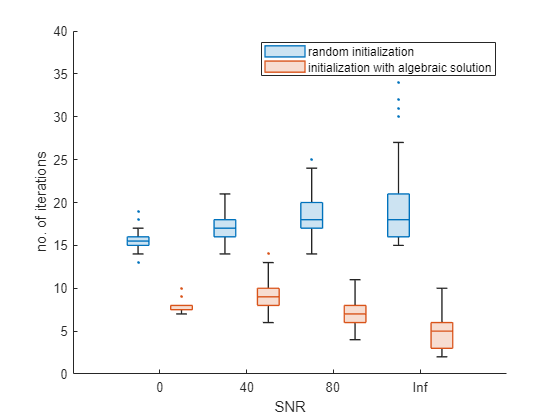

boxchart(categorical(exp_data.SNR),exp_data.iterations,'GroupByColor',exp_data.type,"MarkerStyle",".")
ylabel('no. of iterations')
xlabel('SNR')
%title('iterations required for optimization function(noise on the coeffiecient tensor,\{2,3\} circ)')
legend('random initialization','initialization with algebraic solution')
legend
ylim([0,40])

SNRS = [0,10,20,30];
iters = 100;

%% initialized exp_data %%
init_SNR_iters = [];
rnd_SNR_iters = [];
exp_data.iterations = [];
exp_data.type = [];
exp_data.SNR = ones(1,iters*2)*0;
exp_data.SNR = [exp_data.SNR, ones(1,iters*2)*10];
exp_data.SNR = [exp_data.SNR, ones(1,iters*2)*20];
exp_data.SNR = [exp_data.SNR, ones(1,iters*2)*30];
%% -----------------   %%
for SNR=1:size(SNRS,2)
    init_iterations = [];
    rnd_iterations = [];
    for iter=1:iters
        dim = [20,20,20];
        T = zeros(dim);
        for i = 1:dim(1)
            T(i,:,:) = circulant(randn(dim(2),1));
        end

        x = randn(dim(2),1);
    
        b = tmprod(T,{x.',x.'},[2,3]);
        b_noisy = noisy(b,SNRS(SNR));
        T_noisy = noisy(T,SNRS(SNR));
        T_noisy_dup  = T_noisy;


        F = 1/sqrt(dim(2))*dftmtx(dim(2));
        F_list = {F,conj(F)};
        omega = tmprod(T_noisy_dup,F_list,[2,3]);

        for k = 1:size(T,3)
            filt = zeros(dim(1),dim(2));
            filt(k,k) = 1;
            omega(:,:,k) = omega(:,:,k)*filt;
        end

        y = solve_part_diag(omega,b_noisy);
        xest = F\y;   
     
        U0 = {xest,xest};
        [U,output] = lscpd_nls(T_noisy,b_noisy,U0);
        init_iterations = [init_iterations,output.iterations];

        %%collecting data
        exp_data.iterations = [exp_data.iterations,output.iterations];
        exp_data.type = [exp_data.type,1];
        %%--------------%%

        U0 = cpd_rnd(dim(2:3),1);
        [U2,output2] = lscpd_nls(T_noisy,b_noisy,U0);

        %%collecting data
        rnd_iterations= [rnd_iterations,output2.iterations];
        exp_data.iterations = [exp_data.iterations,output2.iterations];
        exp_data.type = [exp_data.type,0];
        %%--------------%%
    end
    init_SNR_iters = [init_SNR_iters;init_iterations];
    rnd_SNR_iters = [rnd_SNR_iters;rnd_iterations];
end

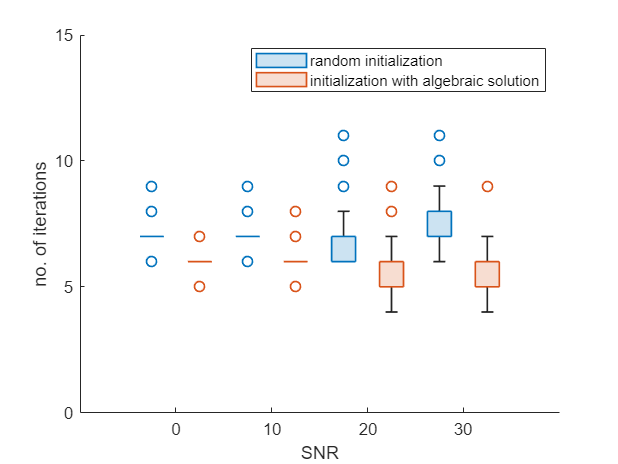

boxchart(categorical(exp_data.SNR),exp_data.iterations,'GroupByColor',exp_data.type)
ylabel('no. of iterations')
xlabel('SNR')
%title('iterations required for optimization function(noise on the coeffiecient tensor,\{2,3\} circ and right hand side b)')
legend('random initialization','initialization with algebraic solution')
legend
ylim([0,15])